# Segmentació per Watershed

openExample('images/WatershedSegmentationExample')

## Netejar l'entorn

clc
close all
clear variables

## Step 1: Read in the Color Image and Convert it to Grayscale

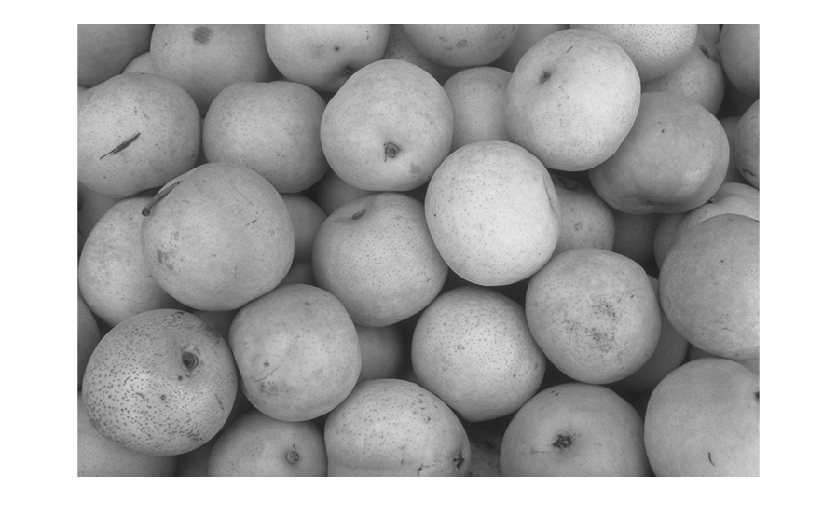

rgb = imread("pears.png");
I = im2gray(rgb);
imshow(I)

## Step 2: Use the Gradient Magnitude as the Segmentation Function

Compute the gradient magnitude. The gradient is high at the borders of the objects and low (mostly) inside the objects.

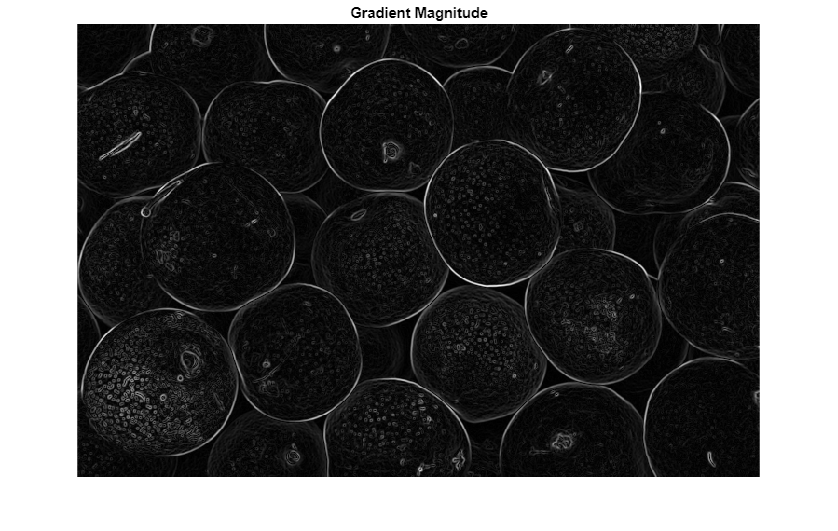

gmag = imgradient(I);
imshow(gmag,[])
title("Gradient Magnitude")

## Step 3: Mark the Foreground Objects

A variety of procedures could be applied here to find the foreground markers, which must be connected blobs of pixels inside each of the foreground objects. In this example, you use morphological techniques called "opening-by-reconstruction" and "closing-by-reconstruction" to "clean" up the image. These operations will create flat maxima inside each object that can be located using `imregionalmax`.

Opening is an erosion followed by a dilation, while opening-by-reconstruction is an erosion followed by a morphological reconstruction. Let's compare the two. First, compute the opening using `imopen`.

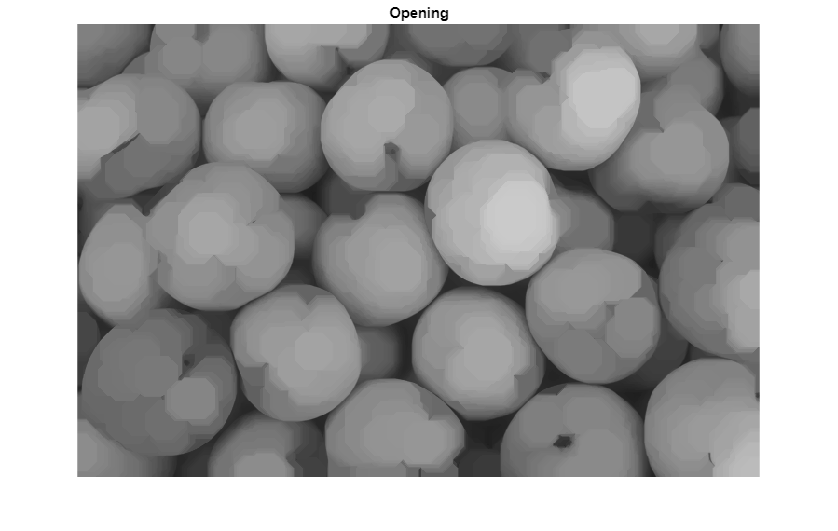

se = strel("disk",20);
Io = imopen(I,se);
imshow(Io)
title("Opening")

Next compute the opening-by-reconstruction using `imerode` and `imreconstruct`.

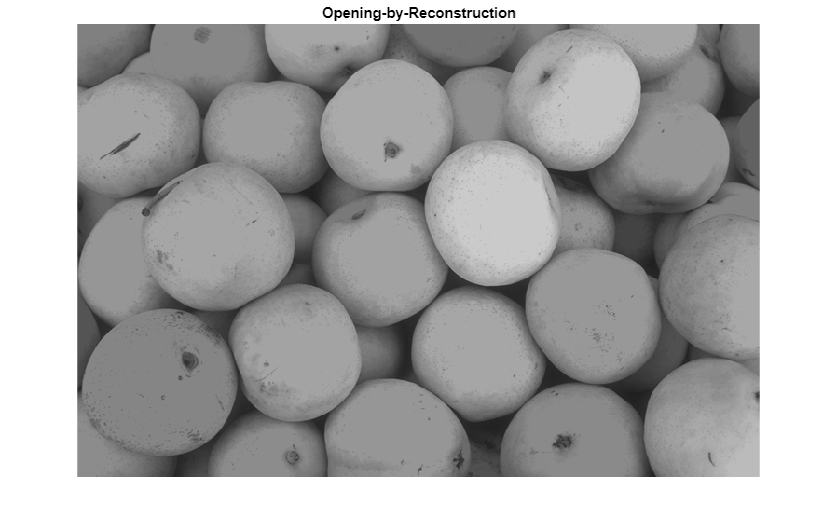

Ie = imerode(I,se);
Iobr = imreconstruct(Ie,I);
imshow(Iobr)
title("Opening-by-Reconstruction")

Following the opening with a closing can remove the dark spots and stem marks. Compare a regular morphological closing with a closing-by-reconstruction. First try `imclose`:

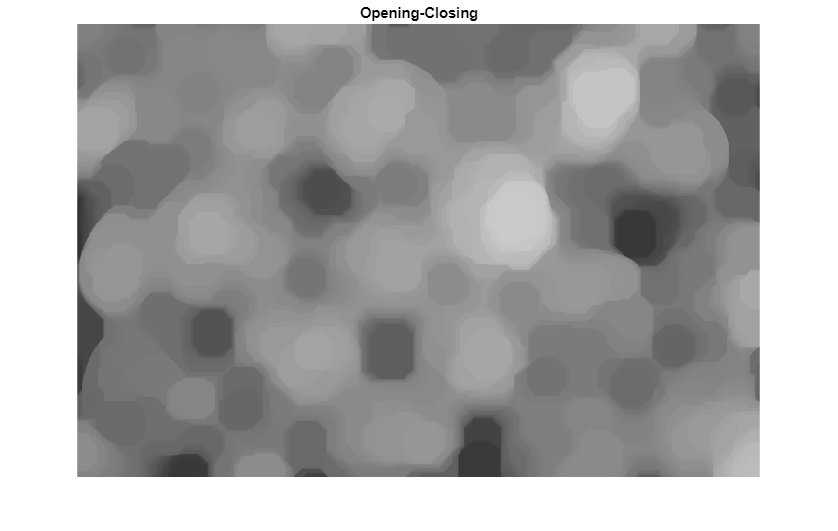

Ioc = imclose(Io,se);
imshow(Ioc)
title("Opening-Closing")

Now use `imdilate` followed by `imreconstruct`. Notice you must complement the image inputs and output of `imreconstruct`.

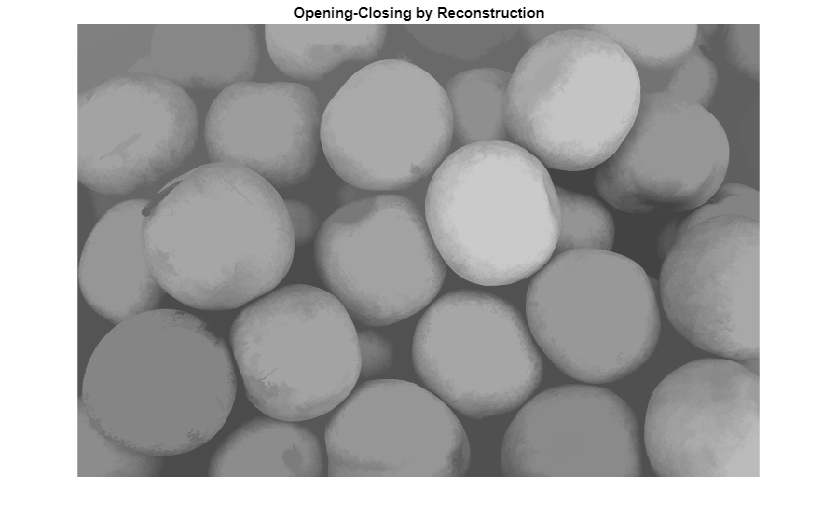

Iobrd = imdilate(Iobr,se);
Iobrcbr = imreconstruct(imcomplement(Iobrd),imcomplement(Iobr));
Iobrcbr = imcomplement(Iobrcbr);
imshow(Iobrcbr)
title("Opening-Closing by Reconstruction")

As you can see by comparing `Iobrcbr` with `Ioc`, reconstruction-based opening and closing are more effective than standard opening and closing at removing small blemishes without affecting the overall shapes of the objects. Calculate the regional maxima of `Iobrcbr` to obtain good foreground markers.

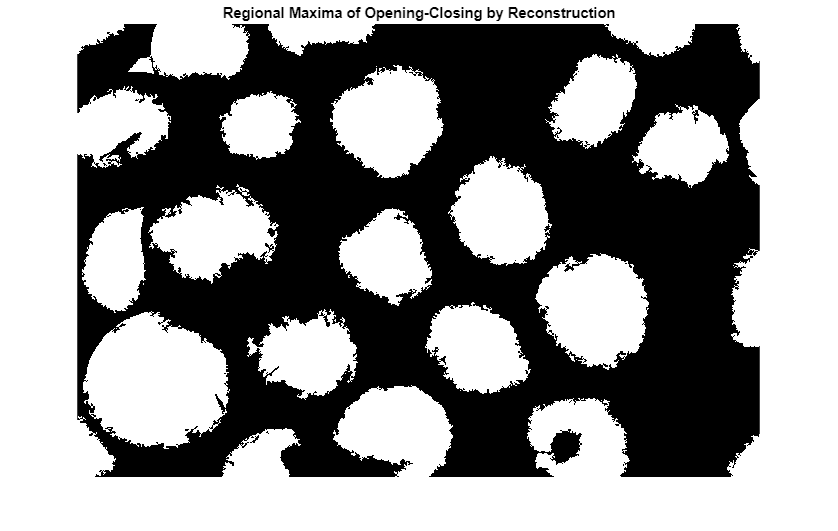

fgm = imregionalmax(Iobrcbr);
imshow(fgm)
title("Regional Maxima of Opening-Closing by Reconstruction")

To help interpret the result, superimpose the foreground marker image on the original image.

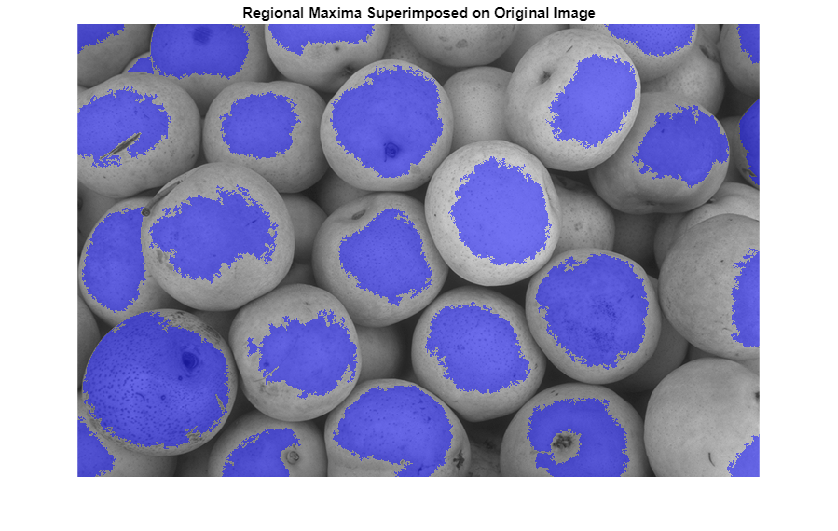

I2 = labeloverlay(I,fgm);
imshow(I2)
title("Regional Maxima Superimposed on Original Image")

Notice that some of the mostly-occluded and shadowed objects are not marked, which means that these objects will not be segmented properly in the end result. Also, the foreground markers in some objects go right up to the objects' edge. That means you should clean the edges of the marker blobs and then shrink them a bit. You can do this by a closing followed by an erosion.

se2 = strel(ones(5,5));
fgm2 = imclose(fgm,se2);
fgm3 = imerode(fgm2,se2);

This procedure tends to leave some stray isolated pixels that must be removed. You can do this using `bwareaopen`, which removes all blobs that have fewer than a certain number of pixels. 

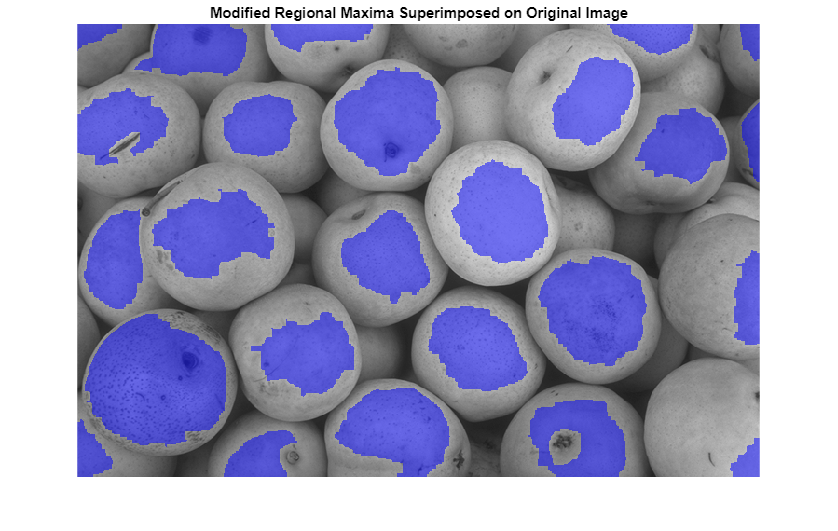

fgm4 = bwareaopen(fgm3,20);
I3 = labeloverlay(I,fgm4);
imshow(I3)
title("Modified Regional Maxima Superimposed on Original Image")

## Step 4: Compute Background Markers

Now you need to mark the background. In the cleaned-up image, `Iobrcbr`, the dark pixels belong to the background, so you could start with a thresholding operation.

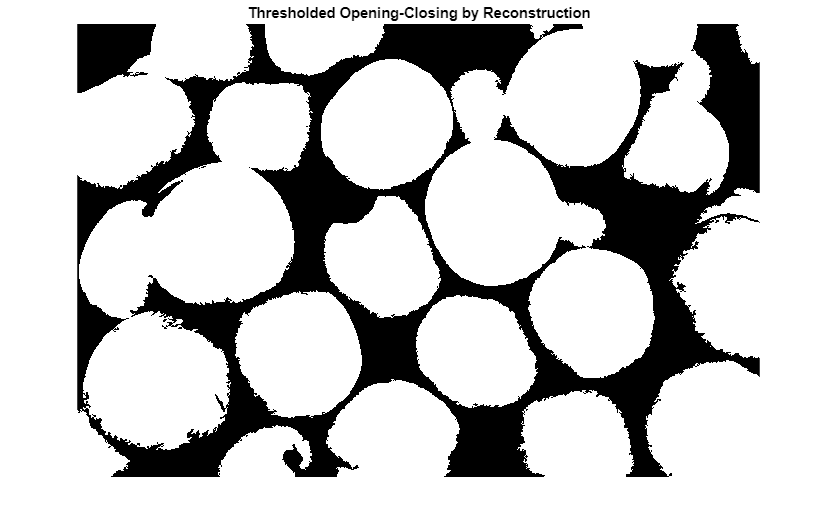

bw = imbinarize(Iobrcbr);
imshow(bw)
title("Thresholded Opening-Closing by Reconstruction")

The background pixels are in black, but ideally we don't want the background markers to be too close to the edges of the objects we are trying to segment. We'll "thin" the background by computing the "skeleton by influence zones", or SKIZ, of the foreground of `bw`. This can be done by computing the watershed transform of the distance transform of `bw`, and then looking for the watershed ridge lines (`DL == 0`) of the result.

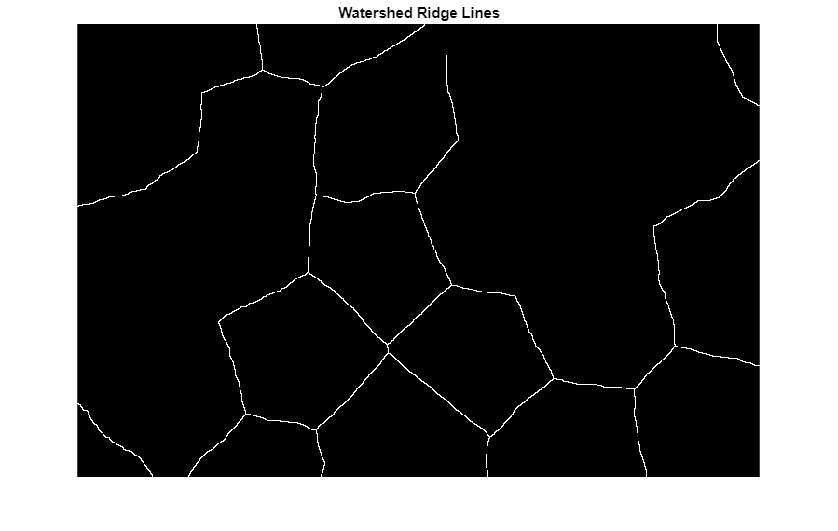

D = bwdist(bw);
DL = watershed(D);
bgm = DL == 0;
imshow(bgm)
title("Watershed Ridge Lines")

## Step 5: Compute the Watershed Transform of the Segmentation Function

The function `imimposemin` can be used to modify an image so that it has regional minima only in certain desired locations. Here you can use `imimposemin` to modify the gradient magnitude image so that its only regional minima occur at foreground and background marker pixels.

gmag2 = imimposemin(gmag, bgm | fgm4);

Finally, compute the watershed-based segmentation.

L = watershed(gmag2);

## Step 6: Visualize the Result

One visualization technique is to superimpose the foreground markers, background markers, and segmented object boundaries on the original image. You can use dilation as needed to make certain aspects, such as the object boundaries, more visible. Object boundaries are located where `L == 0`. The binary foreground and background markers are scaled to different integer values so that they are assigned different labels.

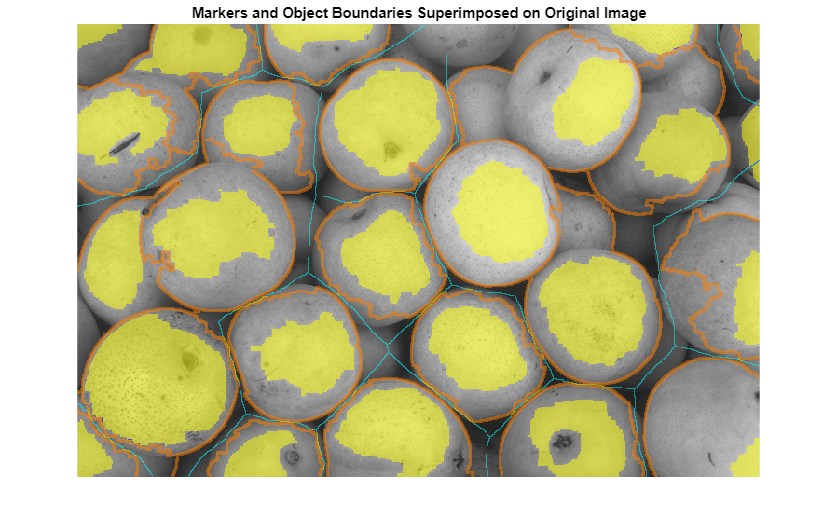

labels = imdilate(L==0,ones(3,3)) + 2*bgm + 3*fgm4;
I4 = labeloverlay(I,labels);
imshow(I4)
title("Markers and Object Boundaries Superimposed on Original Image")

This visualization illustrates how the locations of the foreground and background markers affect the result. In a couple of locations, partially occluded darker objects were merged with their brighter neighbor objects because the occluded objects did not have foreground markers.

Another useful visualization technique is to display the label matrix as a color image. Label matrices, such as those produced by `watershed` and `bwlabel`, can be converted to truecolor images for visualization purposes by using `label2rgb`.

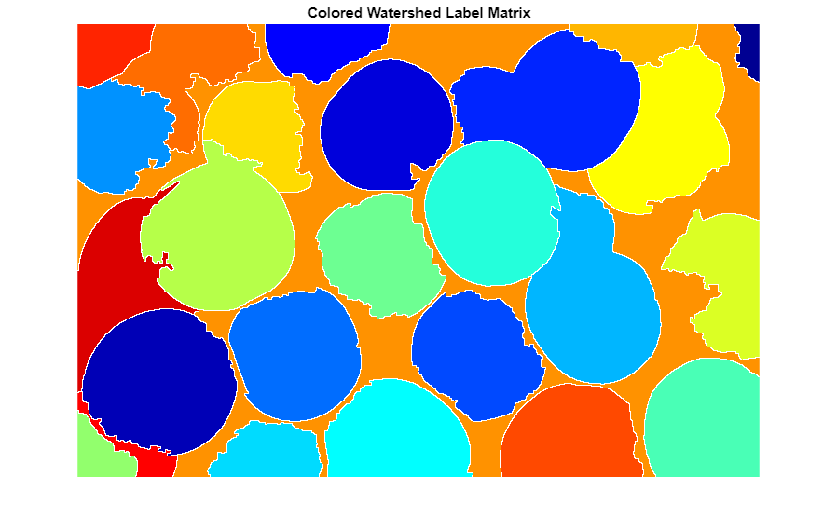

Lrgb = label2rgb(L,"jet","w","shuffle");
imshow(Lrgb)
title("Colored Watershed Label Matrix")

You can use transparency to superimpose this pseudo-color label matrix on top of the original intensity image.

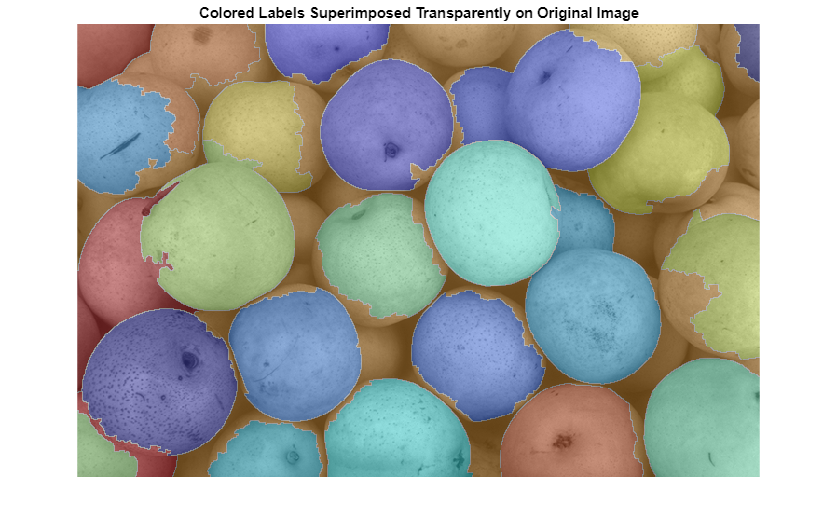

figure
imshow(I)
hold on
himage = imshow(Lrgb);
himage.AlphaData = 0.3;
title("Colored Labels Superimposed Transparently on Original Image")